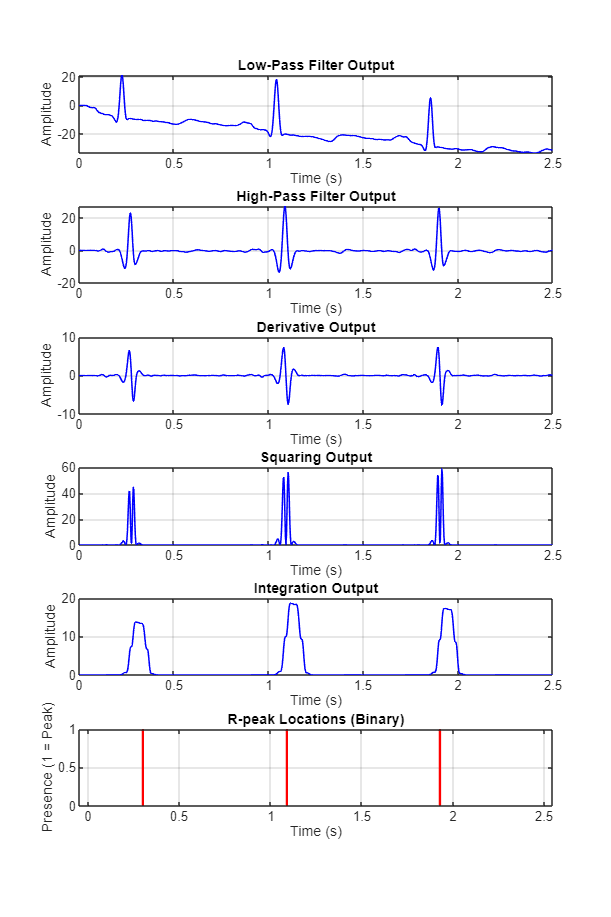

% Load data from files
ecg_signal = load('ecg_data.txt');
y_lp = load('lpf_output.txt');
y_hp = load('hpf_output.txt');
y_der = load('diff_output.txt');
y_sq = load('square_output.txt');
y_int = load('integration_output.txt');
r_peak_binary = load('r_peak_binary.txt'); % Binary array (0s and 1s)

% Time axis (assuming fs = 360 Hz)
fs = 360; % Sampling frequency in Hz
t = (0:length(ecg_signal)-1) / fs;

% Create figure with subplots
figure('Position', [100, 100, 800, 1200]);

% 1. Low-Pass Filter Output
subplot(6, 1, 1);
plot(t, y_lp, 'b', 'LineWidth', 1);
title('Low-Pass Filter Output');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 2. High-Pass Filter Output
subplot(6, 1, 2);
plot(t, y_hp, 'b', 'LineWidth', 1);
title('High-Pass Filter Output');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 3. Derivative Output
subplot(6, 1, 3);
plot(t, y_der, 'b', 'LineWidth', 1);
title('Derivative Output');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 4. Squaring Output
subplot(6, 1, 4);
plot(t, y_sq, 'b', 'LineWidth', 1);
title('Squaring Output');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 5. Integration Output
subplot(6, 1, 5);
plot(t, y_int, 'b', 'LineWidth', 1);
title('Integration Output');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 6. R-peak Binary Signal (Stem Plot)
subplot(6, 1, 6);
stem(t, r_peak_binary, 'r', 'LineWidth', 1.5, 'Marker', 'none');
title('R-peak Locations (Binary)');
xlabel('Time (s)');
ylabel('Presence (1 = Peak)');
grid on;


% Adjust layout
set(gcf, 'Color', 'w');